# Read CSVs

attendance = readtable("school-level-attendance-data-2021.csv", "TextType", "string", ReadVariableNames=true);

masterSchoolData = readtable("master_dataset.csv", "TextType", "string", ReadVariableNames=true);

sa4Regions = readtable("sa4 mapped.xlsx", "TextType", "string", ReadVariableNames=true);
masterSchoolData = outerjoin(masterSchoolData, sa4Regions,"Keys","sa4_region","MergeKeys",true);

retention_rates = readtable("apparent-retention-rates.csv", "TextType", "string", ReadVariableNames=true);

masterSchoolData = outerjoin(masterSchoolData, retention_rates,"Keys","cese_sa4_grouped","MergeKeys",true);

## Join School Attendance to master Dataset

finalTable = outerjoin(attendance, masterSchoolData,"Keys","school_code","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);

%% Select only High Schools
idx = ismember(finalTable.Level_of_schooling, 'Secondary School');
finalTable(~idx, :) = [];

%% Remove/Rename Vars
finalTable = removevars(finalTable, "Level_of_schooling");
finalTable.Properties.VariableNames([3 5]) = {'attendance_pct' 'socio_economic_advantage_value'}

finalTable = 382×12 table
    school_code                             school_name                              attendance_pct    postcode    socio_economic_advantage_value      Selective_school       School_gender          ASGS_remoteness                      sa4_region                 local_health_district          cese_sa4_grouped         x2016_rr_prct
    ___________    ______________________________________________________________    ______________    ________    ______________________________    _____________________    _____________    ___________________________    ___________________________________    _________________


%% Recognise Selective Schools (Selective/Partially = 1, Not Selective = 0)
idx = ismember(finalTable.Selective_school, "Not Selective");
finalTable.Selective_school(idx, :) = 0;
idx = ismember(finalTable.Selective_school, "Partially Selective");
finalTable.Selective_school(idx, :) = 0.5;
idx = ismember(finalTable.Selective_school, "Fully Selective");
finalTable.Selective_school(idx, :) = 1;
finalTable.Selective_school = str2double(finalTable.Selective_school);

%% Recognise Coed Schools (Coed = 1, Not Coed = 0)
idx = ismember(finalTable.School_gender, "Coed");
finalTable.School_gender(~idx, :) = 1;
finalTable.School_gender(idx, :) = 0;
finalTable.School_gender = str2double(finalTable.School_gender);


## Add Crime Data

crime = readtable("Crime.csv", "TextType", "string", ReadVariableNames=true);
population = readtable("breakdown.csv", "TextType", "string", ReadVariableNames=true);
crime = outerjoin(crime, population,"Keys","postcode","MergeKeys",true);
crime = rmmissing(crime, 1);
crime.crimeRate = crime.crimes ./ crime.population;
crime = removevars(crime, ["males", "females", "no_school", "crimes" "population"]);

finalTable = outerjoin(finalTable, crime,"Keys","postcode","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);

## Motor Vehicle

mv = readtable("mv_ownership.csv", "TextType", "string", ReadVariableNames=true);
finalTable = outerjoin(finalTable, mv,"Keys","postcode","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);


## Education Levels

edu = readtable("education.csv", "TextType", "string", ReadVariableNames=true);
edu.postgraduate = edu.postgraduate ./ edu.total_population;
edu.bachelor = edu.bachelor ./ edu.total_population;
edu = removevars(edu, ["total_population"]);

finalTable = outerjoin(finalTable, edu,"Keys","postcode","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);

## Household

households = readtable("household.csv", "TextType", "string", ReadVariableNames=true);
households = removevars(households, ["Average_household_size", "Median_age_persons"]);
finalTable = outerjoin(finalTable, households,"Keys","postcode","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);


## Families

families = readtable("Families.csv", "TextType", "string", ReadVariableNames=true);
families.familiesPrct = (families.Tot_Tot - families.Tot_cpl_fam_no_child) ./ families.Tot_Tot;
families.singleParentPrct = families.Tot_One_parent_fam ./ families.Tot_Tot;
families = removevars(families, ["Tot_cpl_fam_no_child", "Tot_cpl_fam_wth_chld" "Tot_One_parent_fam", "Tot_Tot"]);
finalTable = outerjoin(finalTable, families,"Keys","postcode","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);


## Postcode Tax Data

tax_data = readtable("tax_data.csv", "TextType", "string", ReadVariableNames=true);

tax_data = outerjoin(tax_data, population,"Keys","postcode","MergeKeys",true);
tax_data.buisnessPctPopulation = tax_data.businessWithIncomeNo_ ./ tax_data.population;
tax_data.hlthInsurancePctPopulation = tax_data.peopleWithPrivateHealthInsuranceNo_ ./ tax_data.population;
tax_data.noSchool = tax_data.no_school ./ tax_data.population;
tax_data = removevars(tax_data, ["males", "females", "population", "no_school", "businessWithIncomeNo_" , "peopleWithPrivateHealthInsuranceNo_"]);
finalTable = outerjoin(finalTable, tax_data,"Keys","postcode","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);


## Parents born Overseas

parents_overseas = readtable("parent_birth.csv", "TextType", "string", ReadVariableNames=true);

parents_overseas.TotalPopulation = parents_overseas.TotalPopulation - parents_overseas.NotStated;

parents_overseas.bothParentsBornAusPrct = parents_overseas.TotalBothParentsBornAustralia ./ parents_overseas.TotalPopulation;
parents_overseas.bothParentsBornOverseasPrct = parents_overseas.TotalBothBornOverseas ./ parents_overseas.TotalPopulation;
parents_overseas = removevars(parents_overseas, ["NotStated", "TotalBothBornOverseas", "TotalPopulation", "TotalBothParentsBornAustralia"]);

finalTable = outerjoin(finalTable, parents_overseas,"Keys","postcode","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);

corr(finalTable.attendance_pct, finalTable.bothParentsBornAusPrct,'Row','Complete')

ans = -0.4142

corr(finalTable.attendance_pct, finalTable.bothParentsBornOverseasPrct,'Row','Complete')

ans = 0.3838

## Academic Data

academic = readtable("nsw_sec_schools.csv", "TextType", "string", ReadVariableNames=true);


academic.MalePrct = academic.BoysEnrolments ./ (academic.GirlsEnrolments + academic.BoysEnrolments);

finalTable = outerjoin(finalTable, academic,"Keys","school_name","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);


corr(finalTable.attendance_pct, finalTable.BEScore,'Row','Complete')

ans = 0.7837

corr(finalTable.attendance_pct, finalTable.MalePrct,'Row','Complete')

ans = -0.0649

## Flu Case Rate

flu_case_rate = readtable("flu-cases.csv", "TextType", "string", ReadVariableNames=true);
finalTable = outerjoin(finalTable, flu_case_rate,"Keys","local_health_district","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);

## List Correlations

corr(finalTable.attendance_pct, finalTable.socio_economic_advantage_value,'Row','Complete')

ans = 0.8281

corr(finalTable.attendance_pct, finalTable.Selective_school,'Row','Complete')

ans = 0.4330

corr(finalTable.attendance_pct, finalTable.School_gender,'Row','Complete')

ans = 0.2654

corr(finalTable.attendance_pct, finalTable.crimeRate,'Row','Complete')

ans = -0.4243

corr(finalTable.attendance_pct, finalTable.MV_per_dwelling,'Row','Complete')

ans = 0.5210

corr(finalTable.attendance_pct, finalTable.No_MV_dwellings,'Row','Complete')

ans = 0.1386

corr(finalTable.attendance_pct, finalTable.postgraduate,'Row','Complete')

ans = 0.5564

corr(finalTable.attendance_pct, finalTable.bachelor,'Row','Complete')

ans = 0.5854

corr(finalTable.attendance_pct, finalTable.Average_num_psns_per_bedroom,'Row','Complete')

ans = 0.2985

corr(finalTable.attendance_pct, finalTable.Median_tot_hhd_inc_weekly,'Row','Complete')

ans = 0.5298

corr(finalTable.attendance_pct, finalTable.familiesPrct,'Row','Complete')

ans = 0.0934

corr(finalTable.attendance_pct, finalTable.singleParentPrct,'Row','Complete')

ans = -0.5630

corr(finalTable.attendance_pct, finalTable.noSchool,'Row','Complete')

ans = 0.1207

corr(finalTable.attendance_pct, finalTable.hlthInsurancePctPopulation,'Row','Complete')

ans = 0.4506

corr(finalTable.attendance_pct, finalTable.buisnessPctPopulation,'Row','Complete')

ans = 0.2423


corr(finalTable.attendance_pct, finalTable.x2016_rr_prct,'Row','Complete')

ans = 0.4526

corr(finalTable.attendance_pct, finalTable.flu_case_rate,'Row','Complete')

ans = 0.4380

## Recognise Remotness Schools (Remote  = 1 on Sliding Scale to 0)

idx = ismember(finalTable.ASGS_remoteness, "Remote Australia");
finalTable.ASGS_remoteness(idx, :) = 1;
idx = ismember(finalTable.ASGS_remoteness, "Outer Regional Australia");
finalTable.ASGS_remoteness(idx, :) = 0.66;
idx = ismember(finalTable.ASGS_remoteness, "Inner Regional Australia");
finalTable.ASGS_remoteness(idx, :) = 0.33;
idx = ismember(finalTable.ASGS_remoteness, "Major Cities of Australia");
finalTable.ASGS_remoteness(idx, :) = 0;
finalTable.ASGS_remoteness = str2double(finalTable.ASGS_remoteness);

corr(finalTable.attendance_pct, finalTable.ASGS_remoteness,'Row','Complete')

ans = -0.4268

## Postcode Scores

From here: https://www.abs.gov.au/AUSSTATS/abs@.nsf/DetailsPage/2033.0.55.0012016?OpenDocument

scores = readtable("postcode_score.csv", "TextType", "string", ReadVariableNames=true);

finalTable = outerjoin(finalTable, scores,"Keys","postcode","MergeKeys",true);
finalTable = rmmissing(finalTable, 1)

finalTable = 369×35 table
    school_code                    school_name                     attendance_pct    postcode    socio_economic_advantage_value    Selective_school    School_gender    ASGS_remoteness                sa4_region                 local_health_district     cese_sa4_grouped    x2016_rr_prct    crimeRate    MV_per_dwelling    No_MV_dwellings    postgraduate    bachelor    Average_num_psns_per_bedroom    Median_tot_hhd_inc_weekly    familiesPrct    singleParentPrct    buisnessPctPopulation    hlthInsurancePctPopulation    noSchool     bothParentsBornAusPrct

corr(finalTable.attendance_pct, finalTable.socio_economic_advantage_value,'Row','Complete')

ans = 0.8281

corr(finalTable.attendance_pct, finalTable.EconomicResourcesScore,'Row','Complete')

ans = 0.3943

corr(finalTable.attendance_pct, finalTable.EducationScore,'Row','Complete')

ans = 0.5644

## Religion

relgion = readtable("religion.csv", "TextType", "string", ReadVariableNames=true);

finalTable = outerjoin(finalTable, relgion,"Keys","school_code","MergeKeys",true);
finalTable = rmmissing(finalTable, 1);

corr(finalTable.attendance_pct, finalTable.ReligiousPercentage,'Row','Complete')

ans = -0.0358

## Sort Table

finalTable = sortrows(finalTable, "attendance_pct");

## Normalize Data

finalTable = normalize(finalTable,...
    "DataVariables",...
    ["flu_case_rate", "x2016_rr_prct", "BEScore", "bothParentsBornAusPrct", "bothParentsBornOverseasPrct", "attendance_pct","crimeRate", "socio_economic_advantage_value", "MV_per_dwelling", "postgraduate", "bachelor", "Average_num_psns_per_bedroom", "Median_tot_hhd_inc_weekly", "singleParentPrct", "Socio_economicAdvantageAndDisadvantageScore", "EconomicResourcesScore", "EducationScore"]);

## For Classification Model

finalTable(:, "attendance") = {"Average"}

finalTable = 369×37 table
    school_code                        school_name                        attendance_pct    postcode    socio_economic_advantage_value    Selective_school    School_gender    ASGS_remoteness                   sa4_region                    local_health_district     cese_sa4_grouped    x2016_rr_prct    crimeRate    MV_per_dwelling    No_MV_dwellings    postgraduate    bachelor    Average_num_psns_per_bedroom    Median_tot_hhd_inc_weekly    familiesPrct    singleParentPrct    buisnessPctPopulation    hlthInsurancePctPopulation    noSchool     bothParentsB


excellentIndex = finalTable.attendance_pct > 1;
finalTable.attendance(excellentIndex, :) = "Excellent";

poorIndex = finalTable.attendance_pct < -1;
finalTable.attendance(poorIndex, :) = "Poor";

belowAvgIndex = finalTable.attendance_pct >= -1 & finalTable.attendance_pct <= 0;
finalTable.attendance(belowAvgIndex, :) = "Below Average";

aboveAvgIndex = finalTable.attendance_pct <= 1 & finalTable.attendance_pct >= 0;
finalTable.attendance(aboveAvgIndex, :) = "Above Average";


## Determine best predictors

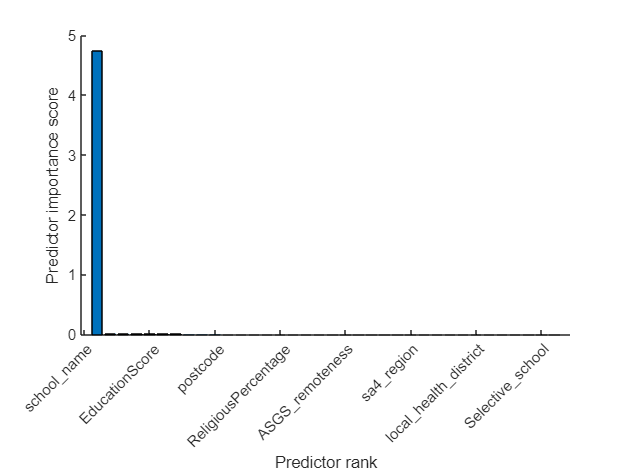

[idx,scores] = fscmrmr(finalTable, "attendance_pct");

hold on
figure(1);
bar(scores(idx))
xlabel('Predictor rank')
ylabel('Predictor importance score')
xticklabels(strrep(finalTable.Properties.VariableNames(idx),'_','\_'))
xtickangle(45)
hold off

## Partion Data

cv          =  cvpartition(height(finalTable),'HoldOut', 0.4);
TRAIN_TABLE =  finalTable(cv.training, :);
TEST_TABLE  =  finalTable(cv.test, :);